clc                     % clear command window
clear                   % clear MATLAB workspace
clf

[robotArduino]= SETUPARDUINO('COM3') 

robotArduino =   arduino with properties:

                  Port: 'COM3'
                 Board: 'Nano33BLE'
         AvailablePins: {'D0-D13', 'A0-A7'}
  AvailableDigitalPins: {'D0-D13', 'A0-A7'}
      AvailablePWMPins: {'D0-D13'}
   AvailableAnalogPins: {'A0-A3', 'A6-A7'}
    AvailableI2CBusIDs: [0, 1]
AvailableSerialPortIDs: [1]
             Libraries: {'I2C', 'Servo'}
Show all properties


steerServo = servo(robotArduino, 'D5', 'MinPulseDuration', 1466*10^-6, ...
      'MaxPulseDuration', 1536*10^-6);
driveServo = servo(robotArduino, 'D3', 'MinPulseDuration', 1466*10^-6, ...
      'MaxPulseDuration', 1536*10^-6);
panServo = servo(robotArduino, 'D6', 'MinPulseDuration', 1466*10^-6, ...
      'MaxPulseDuration', 1536*10^-6);

writePosition(steerServo, 0.5);      % always start servo-command at 0.5
writePosition(driveServo, 0.3);      % always start servo-command at 0.5
writePosition(panServo, 0.5);        % always start servo-command at 0.5
pause(3.0);                          % wait for Arduino to send stable pwm
warning ('actuators live');

% calibrate to 0.1 - 0.3 - 0.9
writePosition(driveServo, 0.3);  % 0.359 to 0.37 for speeds
writePosition(steerServo, 0.51);

joy=vrjoystick(1); 
while true
    one = axis(joy, 1)
    two = axis(joy, 2)
    three = axis(joy, 3)
    writePosition(steerServo, -one*0.16 + 0.54)
    writePosition(driveServo, -two*0.02 + 0.35)
    writePosition(panServo, -three*0.5 + 0.5)
    
    pause(0.01)


end

clear lid
lid = LIDAR('COM6')

lid =   LIDAR with properties:

        lidar: [1×1 serial]
     pol_data: []
    cart_data: []


lidar_data = lid.scan(5000);

lid.close()

gps = NEO_M8U_USB('COM4')


gps_data = gps.getBasic();

clear gps 

lidar_data = lid.scan(10000);
left = lidar_data(:, lidar_data(2,:) > 0 & 0 < lidar_data(1,:) < 500);
plot(left(1,:), left(2,:), '*')
right = lidar_data(:, lidar_data(2,:) < 0 & 0 < lidar_data(1,:) < 500);
plot(right(1,:), right(2,:), '*')
    
lefts = sort(abs(sqrt(left(1,:).^2 + left(2,:).^2)));
rights = sort(abs(sqrt(right(1,:).^2 + right(2,:).^2)));

gpsPlot = figure('Name','Rover Position','NumberTitle','off','Visible','on');
% Zoom down the plot to the Olin Oval coordinates in Latitude and Longitude
geolimits([42.29246 42.29418],[-71.26537 -71.26258])
hold on;
% plot rover poition, you can change this line to plot roverX and RoverY 
gpsPoint = geoplot(42.2935, -71.264, 'r*')
% Import a satellite photo basemap to draw on
geobasemap satellite
legend('Rover GPS Track')
movegui(gpsRoverPlot,'south');
hold off;


plot(lidar_data(1,:), lidar_data(2,:), '*')

save('4-27-lg-01', "lidar_data")

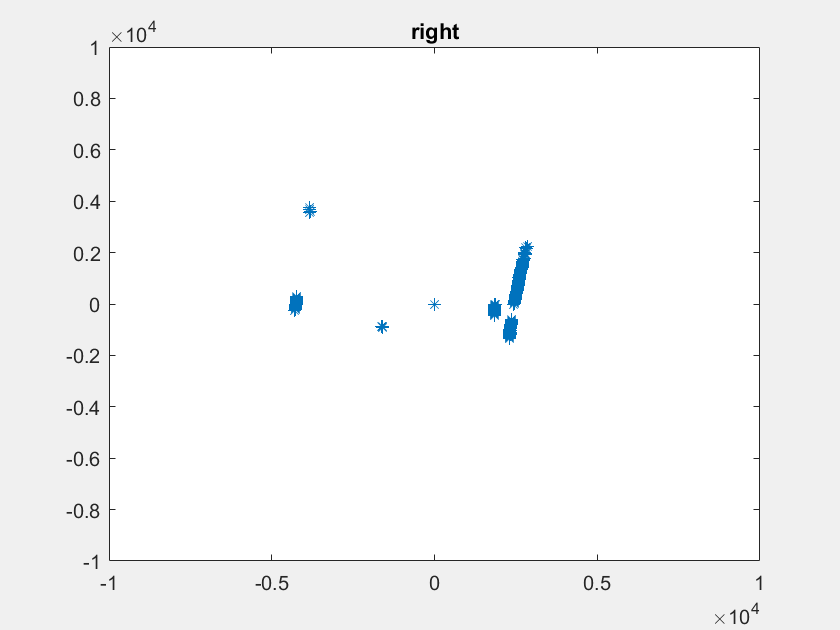

LaserPlot1.figure = figure('Name', 'Hokuyu URG-04LX data', 'NumberTitle','off',...
    'MenuBar','figure','Units','normalized','Visible','on');
LaserPlot1.axis1 = axes('parent', LaserPlot1.figure, 'Units','normalized','NextPlot','replace');
grid(LaserPlot1.axis1, 'on')
LaserPlot1.axis1.Title.String = 'Laser Scans';
LaserPlot1.axis1.XLabel.String = 'X Axis';
LaserPlot1.axis1.YLabel.String = 'Y Axis';

while true
    lidar_data = lid.scan(10000);
    writePosition(driveServo, 0.38)
    left = lidar_data(:, lidar_data(2,:) > 10 & 100 < lidar_data(1,:) < 8000);
    
    right = lidar_data(:, lidar_data(2,:) < -10 & 100 < lidar_data(1,:) < 8000);
    

    hold on
    clf
    %plot x coor, y coord, and object identity
    plot(lidar_data(2,:), lidar_data(1,:), '*')

    %plot -600 to 600 mm for x and y
    range = 10000;
    axis([-range, range, -range, range])
    
    lefts = sort(sqrt(abs(left(1,:).^2) + abs(left(2,:).^2)));
    rights = sort(sqrt(abs(right(1,:).^2) + abs(right(2,:).^2)));

    if isempty(rights)
        rights = [20000; 20000];
    elseif isempty(lefts)
        lefts = [20000; 20000];
    end
    
    if min(lefts) < 7000 & (min(lefts) < min(rights))
        writePosition(steerServo, 0.3*0.16 + 0.52);
        title('left')
    elseif min(rights) < 7000 & (min(rights) < min(lefts))
        writePosition(steerServo, -0.3*0.16 + 0.52);
        title('right')
    else
        writePosition(steerServo, 0.52);
        title('straight')
        rights
    end
    pause(0.5)
end

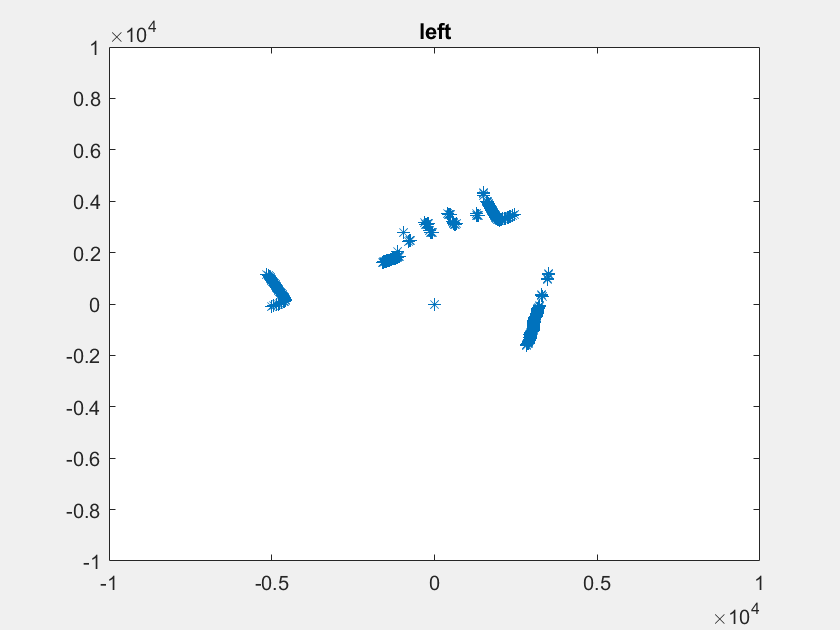

LaserPlot1.figure = figure('Name', 'Hokuyu URG-04LX data', 'NumberTitle','off',...
    'MenuBar','figure','Units','normalized','Visible','on');
LaserPlot1.axis1 = axes('parent', LaserPlot1.figure, 'Units','normalized','NextPlot','replace');
grid(LaserPlot1.axis1, 'on')
LaserPlot1.axis1.Title.String = 'Laser Scans';
LaserPlot1.axis1.XLabel.String = 'X Axis';
LaserPlot1.axis1.YLabel.String = 'Y Axis';

while true
    lidar_data = lid.scan(10000);
    %writePosition(driveServo, 0.37)
    left = lidar_data(:, lidar_data(2,:) > 10 & 400 < lidar_data(1,:) < 2000);
    
    right = lidar_data(:, lidar_data(2,:) > 10 & 400 < lidar_data(1,:) < 2000);
    

    hold on
    clf
    %plot x coor, y coord, and object identity
    plot(lidar_data(2,:), lidar_data(1,:), '*')

    %plot -600 to 600 mm for x and y
    range = 10000;
    axis([-range, range, -range, range])
    
    %lefts = 0.5.*abs(left(1,:)) + 1.5.*abs(left(2,:));
    %rights = 0.5.*abs(right(1,:)) + 1.5.*abs(right(2,:));
    rights = abs(right(2,:));

    if min(rights) < 1500 %& min(rights) < min(lefts)
        writePosition(steerServo, 0.5*0.16 + 0.51);
        title('left')
    elseif min(rights) > 2500 | isempty(rights)
        writePosition(steerServo, -0.5*0.16 + 0.51);
        title('right')
    else
        title('straight')
    end
    pause(0.5)
end

LaserPlot1.figure = figure('Name', 'Hokuyu URG-04LX data', 'NumberTitle','off',...
    'MenuBar','figure','Units','normalized','Visible','on');
LaserPlot1.axis1 = axes('parent', LaserPlot1.figure, 'Units','normalized','NextPlot','replace');
grid(LaserPlot1.axis1, 'on')
LaserPlot1.axis1.Title.String = 'Laser Scans';
LaserPlot1.axis1.XLabel.String = 'X Axis';
LaserPlot1.axis1.YLabel.String = 'Y Axis';

while true
    lidar_data = lid.scan(10000);
    lidar_data = lidar_data(:, 0 < lidar_data(1,:) < 2500);

    direction = 0;

    idx = dbscan(lidar_data, 20, 5);
    
    %Label each point with what cluster it belongs to
    objects = [X(:,1), X(:,2), idx];

    
    %cycle through each object
    for i = 1:max(idx)
        %select one group of points by idx value
        object = objects(objects(:, 3) == i, :);  

        x = mean(objects(:,1));
        y = mean(objects(:,2));
        
        direction = direction + ((y/abs(y))*3*(1/x) + (1/y))/1000;
    end

    hold on
    clf
    %plot x coor, y coord, and object identity
    gscatter(objects(:,1), objects(:, 2), objects(:,3))

    %plot -600 to 600 mm for x and y
    range = 10000;
    axis([-range, range, -range, range])

    if direction < 0.3
        direction = 0.3
    elseif direction > 0.7
        direction = 0.7
    end

    writePosition(steerServo, direction);

end

writePosition(driveServo, 0.35);  % 0.359 to 0.37 for speeds
writePosition(steerServo, 0.51);

gpsPlot = figure('Name','Rover Position','NumberTitle','off','Visible','on');
% Zoom down the plot to the Olin Oval coordinates in Latitude and Longitude
geolimits([42.29246 42.29418],[-71.26537 -71.26258])
hold on;
% plot rover poition, you can change this line to plot roverX and RoverY 
gpsPoint = geoplot(42.2935, -71.264, 'r*')
% Import a satellite photo basemap to draw on
geobasemap satellite
legend('Rover GPS Track')
movegui(gpsRoverPlot,'south');

function [robotArduino]= SETUPARDUINO(COMPORT)
% SETUPARDUINO creates and configures an arduino to be a simple robot test 
% controller. It requires which COM port your Arduino is attached to 
% as its input and returns an Arduino object called robotArduino
% D. Barrett 2022 Rev2
% Create a arduino object so that it can be used in functions
% a = arduino('setToYourComNumber','Uno','Libraries','Servo');
   robotArduino = arduino(COMPORT,'Nano33BLE',"Libraries",{'Servo','I2C'});
end

function wave, waypoints = gpsWaypoint(gps_data, waypoints)
    [dist, angle] = distance(gps_data.latitude, gps_data.longitude, wlat, wlon);
    if dist < cutoff
        waypoints(0) = [];
    end
    delta = angdiff(gps_data.heading, angle);
    if delta > pi/2
        wave = spline([-3 -2 -1 0 1 2 3], [0 0 0 0 0 1 2]);
    elseif delta > 0
        wave = spline([-3 -2 -1 0 1 2 3], [0 0 0 1 2 0 0]);
    elseif delta < -pi/2
        wave = spline([-3 -2 -1 0 1 2 3], [2 1 0 0 0 0 0]);
    else
        wave = spline([-3 -2 -1 0 1 2 3], [0 0 2 1 0 0 0]);
    end
end

function wave = lidarWallFollow(lidar_data)
    left = lidar
end
